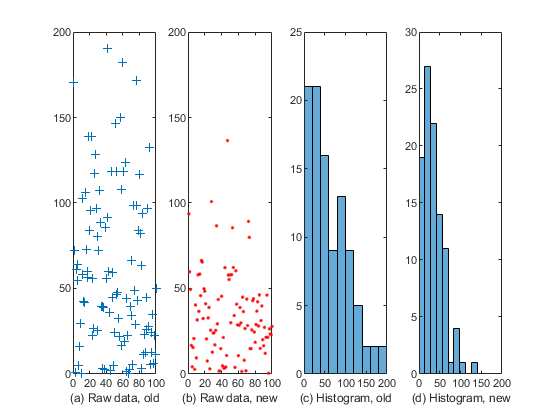

clear all;
close all;

fin = fopen('sgbdold.dat','r');
data_old = fscanf(fin,'%f');
fclose(fin);
fin = fopen('sgbdnew.dat','r');
data_new = fscanf(fin,"%f");
fclose(fin);

subplot(1,4,1);
plot(data_old,'+');
xlabel('(a) Raw data, old');
xticks([0 20 40 60 80 100]);
ylim([0 200]);
yticks([0 50 100 150 200]);
subplot(1,4,2);
plot(data_new,'.r');
xlabel('(b) Raw data, new');
xticks([0 20 40 60 80 100]);
ylim([0 200]);
yticks([0 50 100 150 200]);
subplot(1,4,3);
histogram(data_old,'NumBins',10);
xlabel('(c) Histogram, old');
xlim([0 200]);
xticks([0 50 100 150 200]);
subplot(1,4,4);
histogram(data_new,'NumBins',10);
xlabel('(d) Histogram, new');
xlim([0 200]);
xticks([0 50 100 150 200]);